clear all;
close all;

JND = 2.3

JND = 2.3000


negative = [255, 182, 70];
hemolyzedTrace = [185, 183, 72];
small = [135, 161, 69];
med = [78, 125, 66];
large = [50, 73, 52];

dipStickColors = [negative; hemolyzedTrace; small; med; large]

dipStickColors =    255   182    70
   185   183    72
   135   161    69
    78   125    66
    50    73    52



c_negative = [210, 160, 42];
c_hemolyzedTrace = [198, 161, 46];
c_small = [159, 150, 47];
c_med = [116, 124, 58];
c_large = [55, 75, 47];

reference = [c_negative; c_hemolyzedTrace; c_small; c_med; c_large]

reference =    210   160    42
   198   161    46
   159   150    47
   116   124    58
    55    75    47



c_coef = dipStickColors./reference;


location = fullfile('dipsticks');
ds = imageDatastore(location,'FileExtensions',{'.jpg','.tif','.png'});
lbls = filenames2labels(location,FileExtensions=".jpg")

lbls = 72×1 categorical array
     10_1n1_exp2 
     10_1n1_exp3 
     10_1n2_exp2 
     10_1n2_exp3 
     10_1n3_exp2 
     10_1n3_exp3 
     10_2n1_exp2 
     10_2n1_exp3 
     10_2n2_exp2 
     10_2n2_exp3 
     10_2n3_exp2 
     10_2n3_exp3 
     200_1n1_exp2 
     200_1n1_exp3 
     200_1n2_exp2 
     200_1n2_exp3 
     200_1n3_exp2 
     200_1n3_exp3 
     200_2n1_exp2 
     200_2n1_exp3 
     200_2n2_exp2 
     200_2n2_exp3 
     200_2n3_exp2 
     200_2n3_exp3 
     20_1n1_exp2 
     20_1n1_exp3 
     20_1n2_exp2 
     20_1n2_exp3 
     20_1n3_exp2 
     20_1n3_exp3 


labels = uint8(length(lbls));

for i = 1:length(lbls)
    filename = string(lbls(i));
    %     filename(find(filename == '.',1,'last'):end) = []; %remove extensio
    C = regexp(filename, '_', 'split');
    l = string(C(1));

    labels(i) =  str2num(l);
end

w = 10;
h = 10;
nimage = length(ds.Files);
imDim = [h w];



rsImages = uint8(zeros(h, w, 3, nimage));
aveColor = uint8(zeros(nimage, 3));
for i = 1:nimage
    data = readimage(ds,i);
    t = imresize(data, imDim);
    rsImages(:, :, :, i) = t;
    aveColor(i, :) = [mean(mean(t(:, :, 1))); mean(mean(t(:, :, 2)));  mean(mean(t(:, :, 3)))];

end

for i = 1:nimage
    t =  uint8([aveColor(i, 1); aveColor(i, 2); aveColor(i, 3)]);
    c(i,1, 1:3) = t;
end


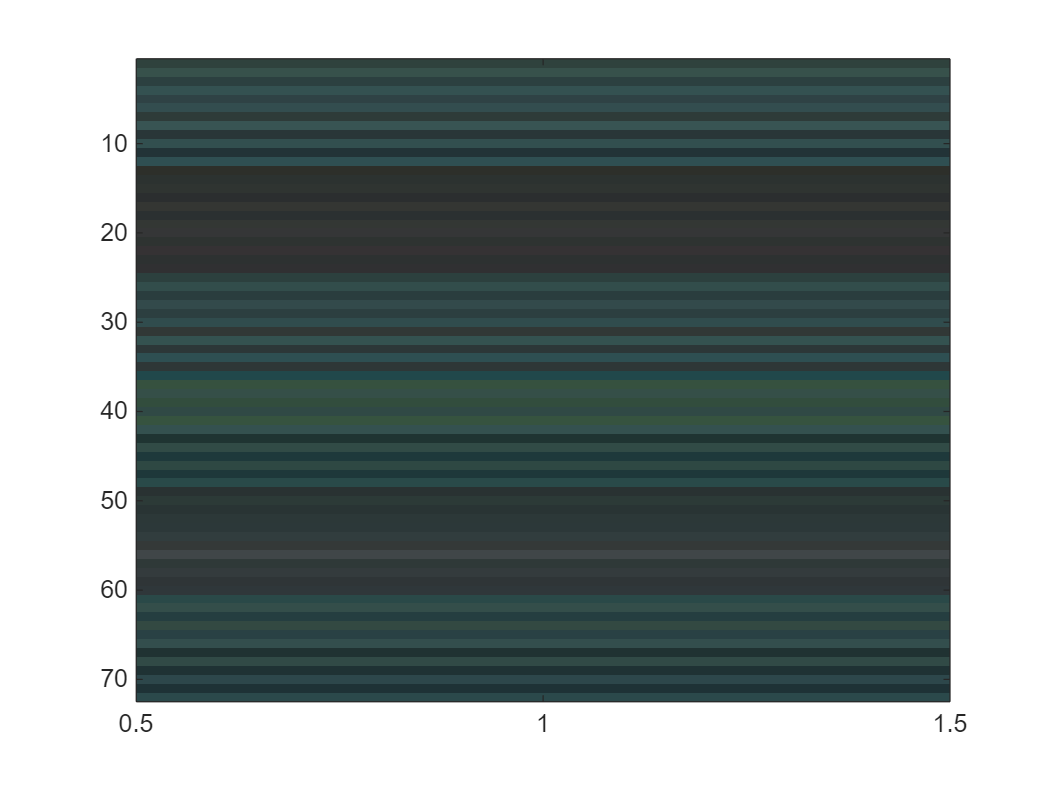

image(c)

data = [labels' aveColor]

data = 72×4 uint8 matrix
   10   47   66   61
   10   55   81   75
   10   44   64   64
   10   52   81   81
   10   47   66   69
   10   51   77   79
   10   46   59   57
   10   56   84   83
   10   41   54   56
   10   50   79   79


data = sort(data, 'ascend');
lbls = data(:, 1);
aveColor = data(:, 2:end);

de = zeros(nimage, nimage);

for i = 1:nimage
    a = (aveColor(i, :));
    for j = 1:nimage
        b = (aveColor(j, :));
        de(i, j) = imcolordiff(a,b,"Standard","CIEDE2000");%, "isInputLab", true);
        %         de(i, j) = deltaE(a,b, "isInputLab", true);
    end
end

de_JND = zeros(nimage, nimage);

for i = 1:nimage
    for j = 1:nimage
        t = de(i, j);

        if t <= JND
            t = 0;
        end
        de_JND(i, j) = t;
    end
end

for i = 1:nimage
    t =  uint8([aveColor(i, 1); aveColor(i, 2); aveColor(i, 3)]);
    c(i,1, 1:3) = t;
end


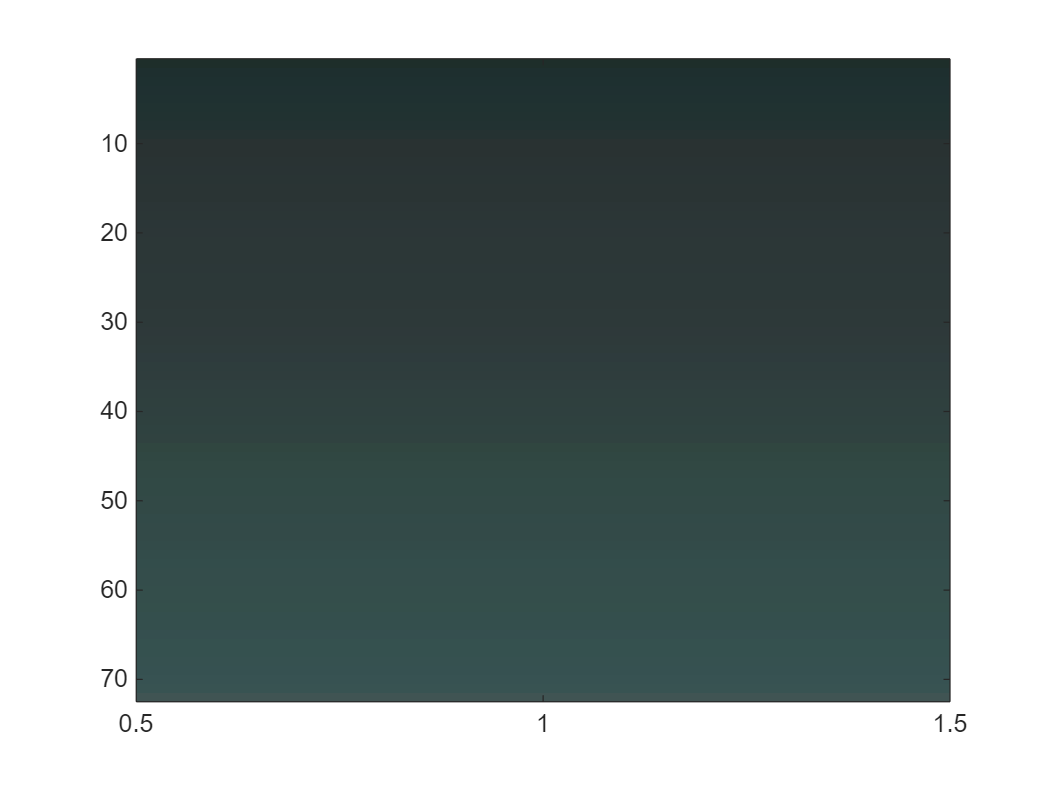

image(c)


jndThreshold = 0;

for i = 2:nimage
    j = i -1;
    a = (aveColor(i, :));
    b = (aveColor(j, :));
    deCount(i) = imcolordiff(a,b,"Standard","CIEDE2000");%, "isInputLab", true);

    if(deCount(i) >= JND && jndThreshold ~= 0)
        jndThreshold = lbls(i);
    end
end


numGT = length(dipStickColors);
de_gt = zeros(numGT, nimage);
for i = 1:numGT-1
    t =  uint8([reference(i+1, 1); reference(i+1, 2); reference(i+1, 3)]);
    r(i,1, 1:3) = t;
end

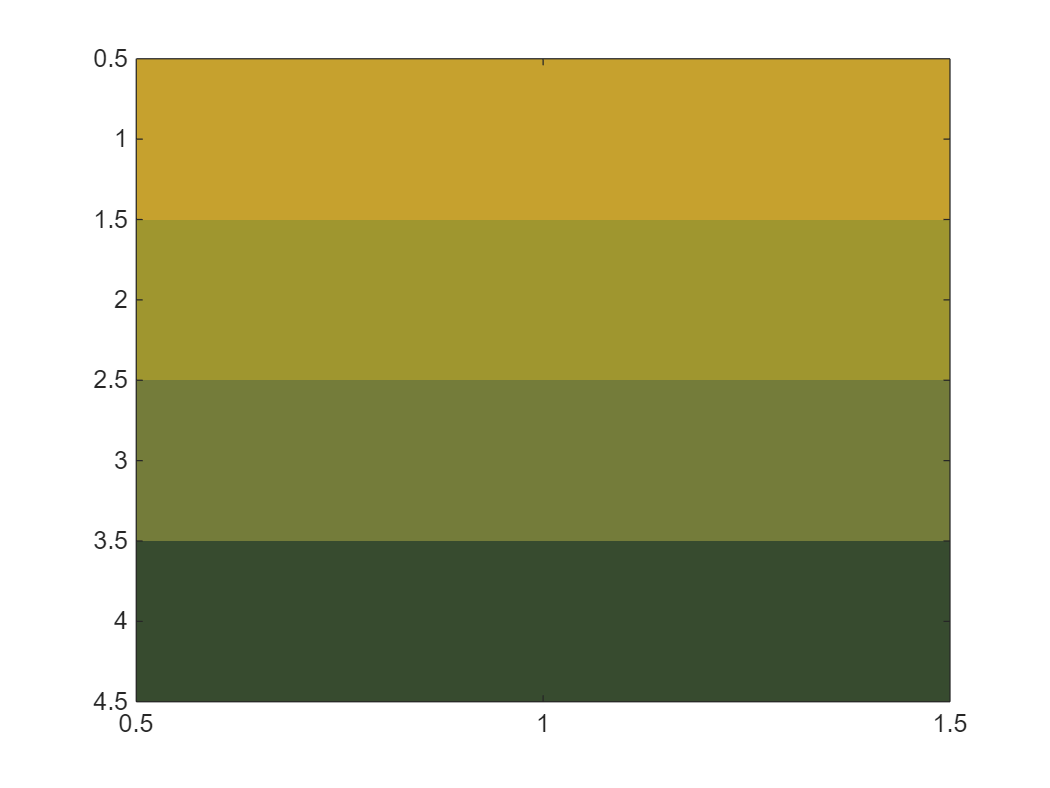

image(r)

for i = 1:numGT
    a = (reference(i, :));

    for j = 1:nimage
        b = (aveColor(j, :));
        de_gt(i, j) = imcolordiff(a,b,"Standard","CIEDE2000");%, "isInputLab", true);
    end
end


dE_ref = zeros(numGT, numGT);

for i = 1:numGT
    a = (reference(i, :));
    for j = 1:numGT
        b = (reference(j, :));
        t = imcolordiff(a,b,"Standard","CIEDE2000");
        dE_ref(i, j) = t;
    end
end


max_de_GT = max(max(de_gt))

max_de_GT = 139.2310

r = round(max_de_GT);
image(de_gt)
colormap(flipud(colormap(parula(r))))
c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [1 140]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


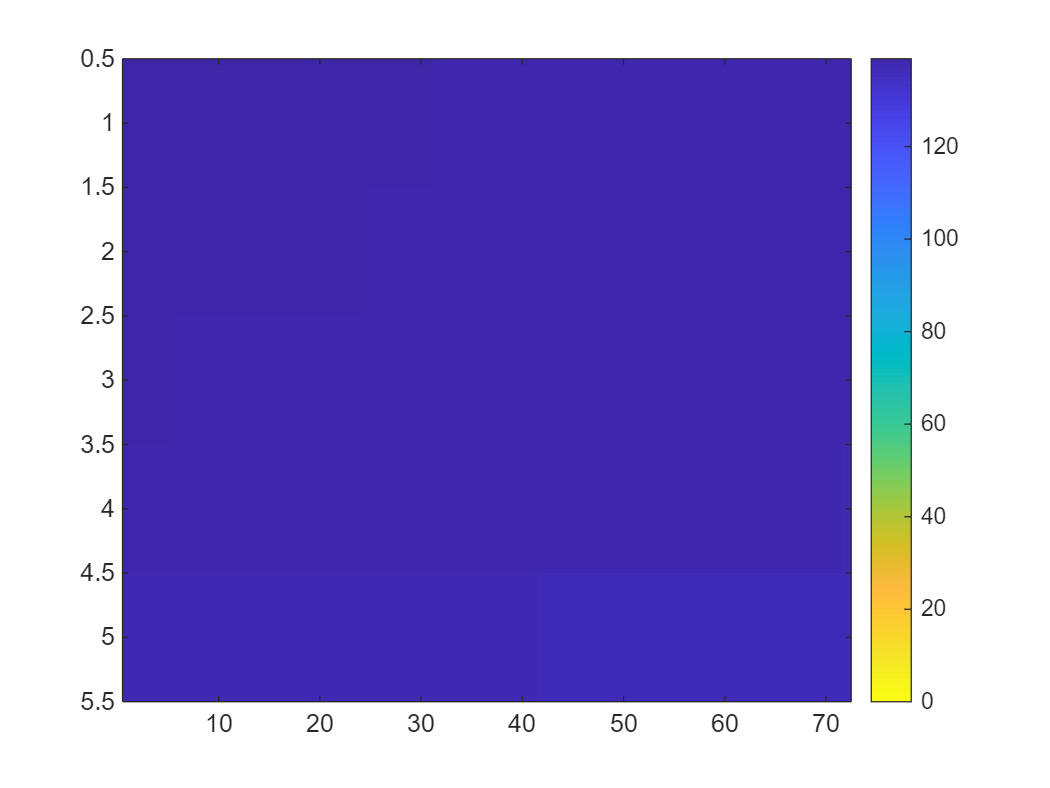

c.Limits = [0 r];


max_gt = max(max(dE_ref))

max_gt = 76.9100

r = round(max_gt);

image(dE_ref)
colormap(parula(r))
c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [1 78]
    FontSize: 9
    Position: [0.8131 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


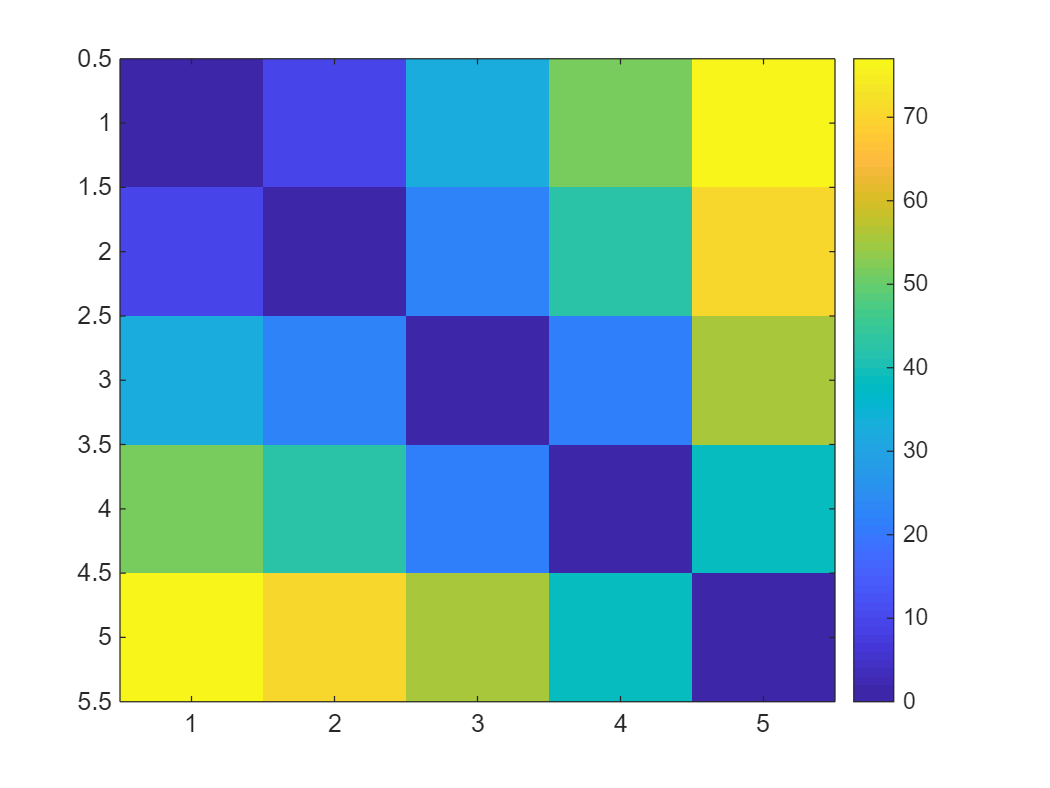

c.Limits = [0 r];


maxDE = max(max(de))

maxDE = 12.4346

r = round(maxDE);
image(de);
colormap(flipud(colormap(parula(r))))

yline(12, 'r', 'LineWidth',2);
yline(24, 'r', 'LineWidth',2);
yline(36, 'r', 'LineWidth',2);
yline(48, 'r', 'LineWidth',2);
yline(60, 'r', 'LineWidth',2);

xline(12, 'r', 'LineWidth',2);
xline(24, 'r', 'LineWidth',2);
xline(36, 'r', 'LineWidth',2);
xline(48, 'r', 'LineWidth',2);
xline(60, 'r', 'LineWidth',2);

c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [1 13]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


c.Limits = [0 r];

tick_val = 6 + (0:12:60);
tick_labels = arrayfun(@num2str, 4*double(unique(labels)), 'UniformOutput', 0)

tick_labels = 1×6 cell array
    {'8'}    {'20'}    {'40'}    {'80'}    {'200'}    {'800'}


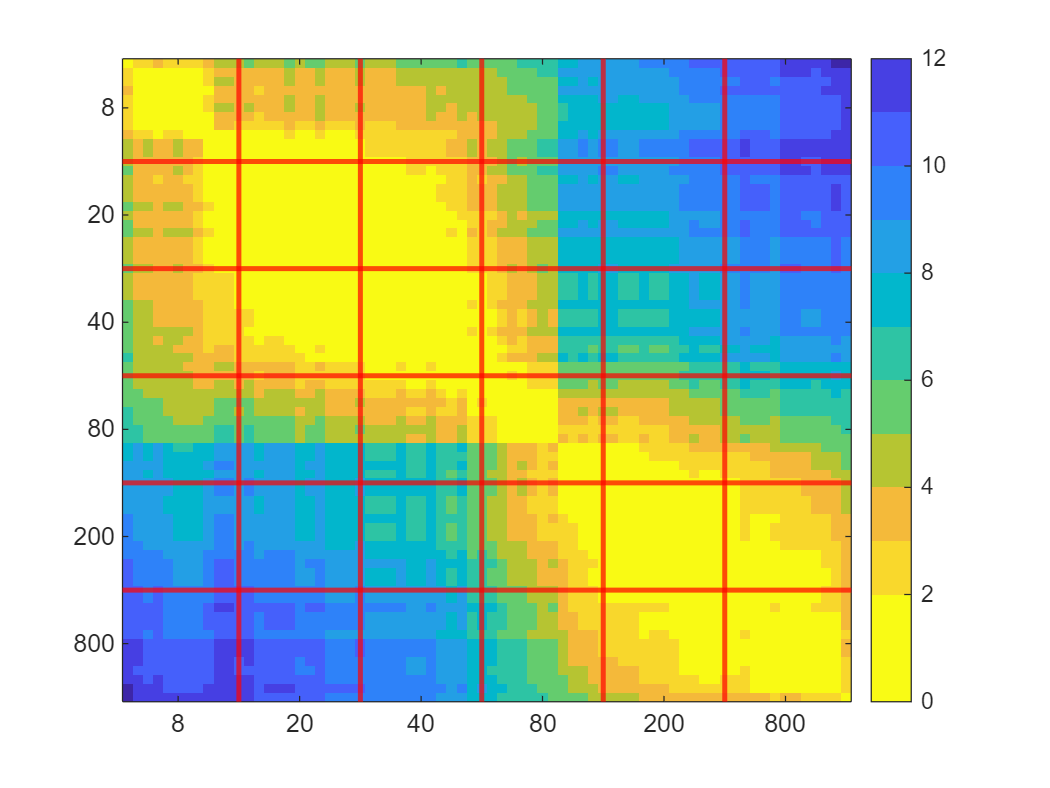


yticks(tick_val)
yticklabels(tick_labels);
xticks(tick_val)
xticklabels(tick_labels);

set(gca,'TickLabelInterpreter', 'tex')

colorGrid = ones(13,3);
gradient = [1,1,0.5:-0.05:0];
% gradient(end) = [];
for i = 1:length(colorGrid(:,1))
    colorGrid(i,:) = [gradient(i),0,0];
end


colorGrid = jet;
colorGrid(1:49,:) = ones(49,3);

maxJND = max(max(de_JND))

maxJND = 12.4346

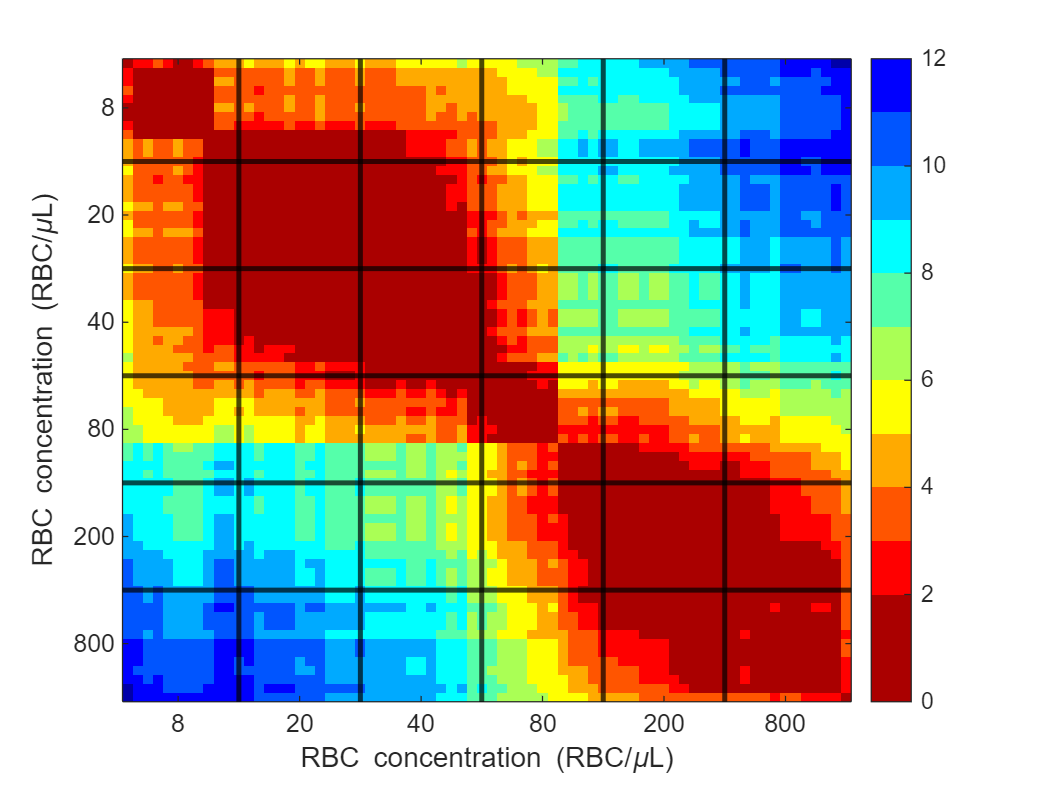

r = round(maxJND);
 colormap(colorGrid);
colormap(flipud(colormap(jet(r))))

% colormap(flipud(colormap(colorGrid(r))))


image(de_JND);
yline(12, 'k', 'LineWidth',2);
yline(24, 'k', 'LineWidth',2);
yline(36, 'k', 'LineWidth',2);
yline(48, 'k', 'LineWidth',2);
yline(60, 'k', 'LineWidth',2);
%
xline(12, 'k', 'LineWidth',2);
xline(24, 'k', 'LineWidth',2);
xline(36, 'k', 'LineWidth',2);
xline(48, 'k', 'LineWidth',2);
xline(60, 'k', 'LineWidth',2);
c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [1 13]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


c.Limits = [0 r];
tick_val = 6 + (0:12:60);
tick_labels = arrayfun(@num2str, 4*double(unique(labels)), 'UniformOutput', 0)

tick_labels = 1×6 cell array
    {'8'}    {'20'}    {'40'}    {'80'}    {'200'}    {'800'}


% set(colorbar,'visible','off')
yticks(tick_val)
yticklabels(tick_labels);
xticks(tick_val)
xticklabels(tick_labels);
set(gca,'TickLabelInterpreter', 'tex')
xlabel('RBC concentration (RBC/\muL)')
ylabel('RBC concentration (RBC/\muL)')

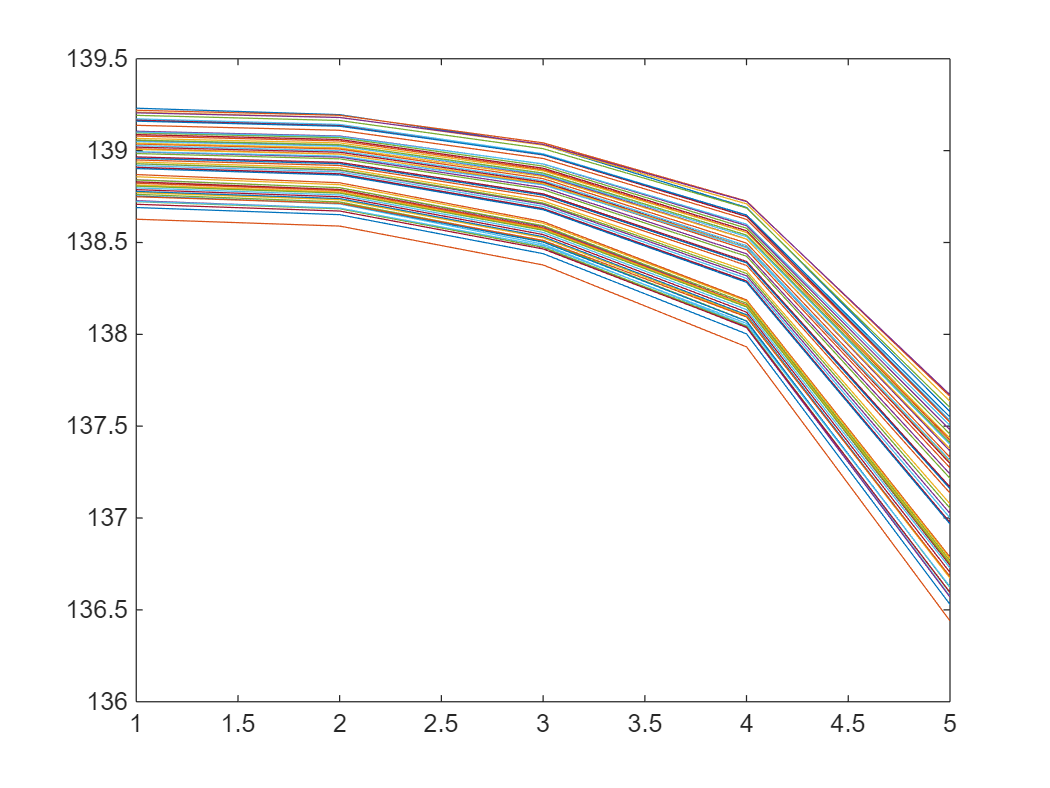

plot(de_gt)

% colorcloud(data, 'lab')


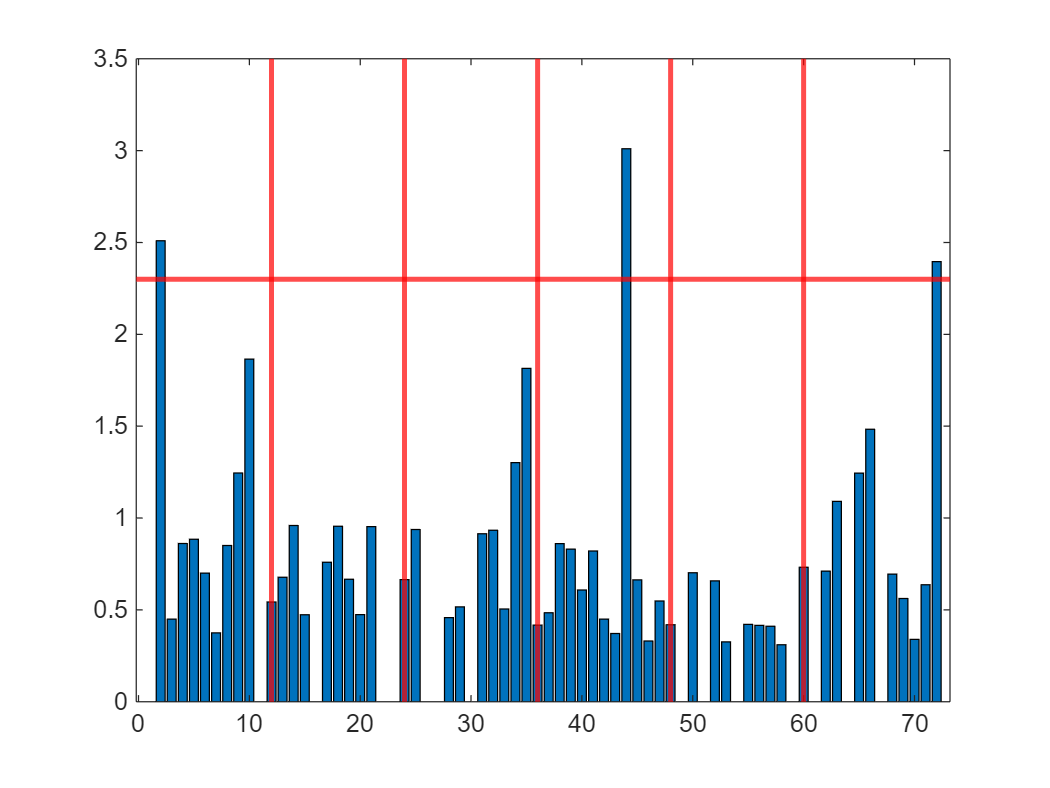

figure;
bar(deCount); hold on,
yline(JND, 'r', 'LineWidth',2);

xline(12, 'r', 'LineWidth',2);
xline(24, 'r', 'LineWidth',2);
xline(36, 'r', 'LineWidth',2);
xline(48, 'r', 'LineWidth',2);
xline(60, 'r', 'LineWidth',2);
hold off;

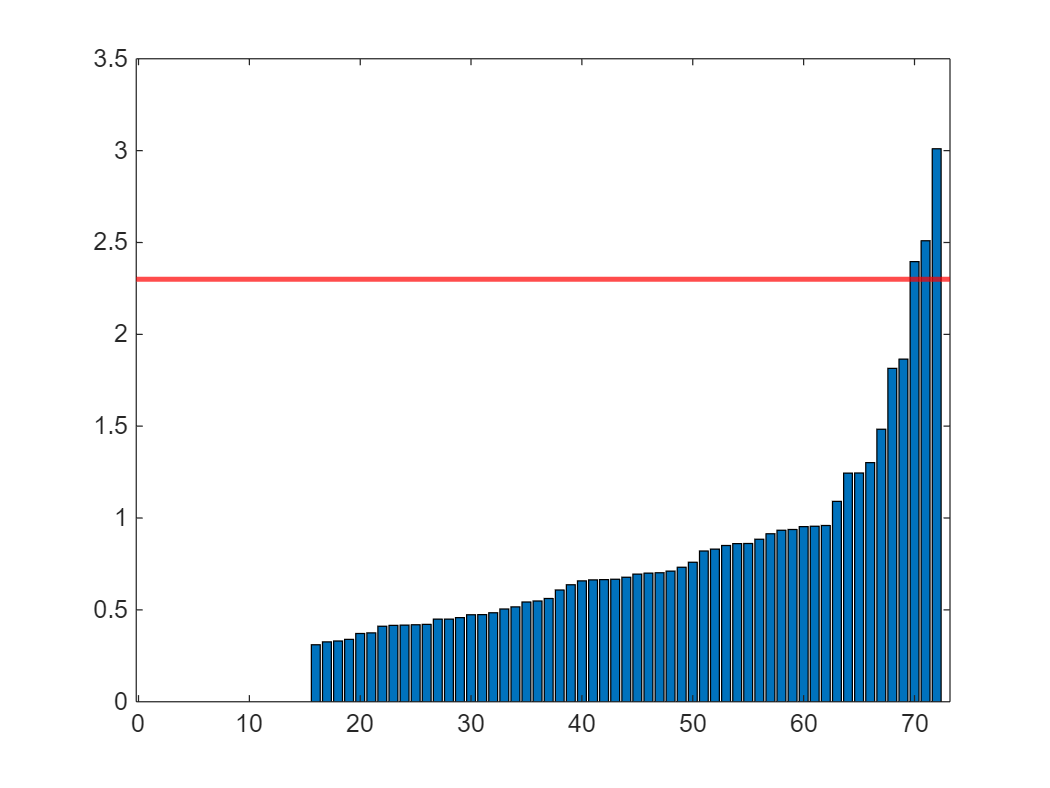

dc = sort(deCount, "ascend");
xCenter = 70;
yCenter = JND;
figure;

bar(dc); hold on,
yline(JND, 'r', 'LineWidth',2);
hold off;